% Presetting
syms x y z omega phi psi;
PosExtract=[0; 0; 0; 1];

PosExtract =      0
     0
     0
     1


p(x, y, z)=[x; y; z];

$$p(x, y, z) = \left(\begin{array}{c} x\\ y\\ z \end{array}\right)$$

Rotx(omega)=[1  0   0
            0   cos(omega)  -sin(omega)
            0   sin(omega)  cos(omega)];

$$Rotx(omega) = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\omega \right) & -\sin\left(\omega \right)\\ 0 & \sin\left(\omega \right) & \cos\left(\omega \right) \end{array}\right)$$

Roty(phi)=[cos(phi) 0   sin(phi)
            0   1   0
            -sin(phi)   0   cos(phi)];

$$Roty(phi) = \left(\begin{array}{ccc} \cos\left(\varphi \right) & 0 & \sin\left(\varphi \right)\\ 0 & 1 & 0\\ -\sin\left(\varphi \right) & 0 & \cos\left(\varphi \right) \end{array}\right)$$

Rotz(psi)=[cos(psi) -sin(psi)   0
            sin(psi)    cos(psi)    0
            0   0   1];

$$Rotz(psi) = \left(\begin{array}{ccc} \cos\left(\psi \right) & -\sin\left(\psi \right) & 0\\ \sin\left(\psi \right) & \cos\left(\psi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

% Body Kinematics
syms L W omega phi psi xm ym zm;

% Global to Body
anglemx=omega;
anglemy=phi;
anglemz=psi;
pm=[xm ym zm].';



% Right Front Leg Kinematics
syms L1 L2xy L2z L3 theta1 theta2 theta3

% Right Front Shoulder to Preprocessing UpperArm
angle01=theta1;

$$angle01 = \theta_{1}$$

p01=p(0,0,L1);

$$p01 = \left(\begin{array}{c} 0\\ 0\\ L_{1} \end{array}\right)$$

Rot01=Rotz(angle01);

$$Rot01 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

T01=HomogeneousTransform(Rot01, p01, 1)

$$T01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Right Front Preprocessing UpperArm to UpperArm
angle12z=-pi/2;

angle12z = -1.5708

angle12x=pi/2;

angle12x = 1.5708

p12=p(0, 0, 0);

$$p12 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Rot12=Rotz(angle12z)*Rotx(angle12x);

$$Rot12 = \left(\begin{array}{ccc} 0 & 0 & -1\\ -1 & 0 & 0\\ 0 & 1 & 0 \end{array}\right)$$

T12=HomogeneousTransform(Rot12, p12, 1)

$$T12 = \left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ -1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Right Front UpperArm to LowArm
angle23=theta2;

$$angle23 = \theta_{2}$$

p23=p(L2xy*cos(theta2),L2xy*sin(theta2),L2z);

$$p23 = \left(\begin{array}{c} \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\\ \mathrm{L2xy}\,\sin\left(\theta_{2}\right)\\ \mathrm{L2z} \end{array}\right)$$

Rot23=Rotz(angle23);

$$Rot23 = \left(\begin{array}{ccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

T23=HomogeneousTransform(Rot23, p23, 1)

$$T23 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & \mathrm{L2xy}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & \mathrm{L2z}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Right Front LowArm to Foot
angle34=theta3;

$$angle34 = \theta_{3}$$

p34=p(L3*cos(theta3),L3*sin(theta3),0);

$$p34 = \left(\begin{array}{c} L_{3}\,\cos\left(\theta_{3}\right)\\ L_{3}\,\sin\left(\theta_{3}\right)\\ 0 \end{array}\right)$$

Rot34=Rotz(angle34);

$$Rot34 = \left(\begin{array}{ccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

T34=HomogeneousTransform(Rot34, p34, 1)

$$T34 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & L_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & L_{3}\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Right Front Shoulder to UpperArm
T02=T01*T12

$$T02 = \left(\begin{array}{cccc} \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ -\cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T02=simplify(T02)

$$T02 = \left(\begin{array}{cccc} \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ -\cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Right Front Shoulder to LowArm
T03=T02*T23

$$T03 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right) & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\mathrm{L2z}\,\cos\left(\theta_{1}\right)\\ -\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & -\mathrm{L2z}\,\sin\left(\theta_{1}\right)-\mathrm{L2xy}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & L_{1}+\mathrm{L2xy}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03=simplify(T03)

$$T03 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right) & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\mathrm{L2z}\,\cos\left(\theta_{1}\right)\\ -\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & -\mathrm{L2z}\,\sin\left(\theta_{1}\right)-\mathrm{L2xy}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & L_{1}+\mathrm{L2xy}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Right Front Shoulder to Foot
T04=T03*T34

$$T04 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & -\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right) & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\mathrm{L2z}\,\cos\left(\theta_{1}\right)+L_{3}\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-L_{3}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & L_{3}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\mathrm{L2xy}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-L_{3}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\mathrm{L2z}\,\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & 0 & L_{1}+\mathrm{L2xy}\,\sin\left(\theta_{2}\right)+L_{3}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+L_{3}\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T04=simplify(T04)

$$T04 = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\mathrm{L2z}\,\cos\left(\theta_{1}\right)+L_{3}\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-L_{3}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ -\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & L_{3}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\mathrm{L2xy}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-L_{3}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\mathrm{L2z}\,\sin\left(\theta_{1}\right)\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & L_{1}+L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+\mathrm{L2xy}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Right Front Leg Kinematics test by plot graph

% Right Front Shoulder to Preprocessing UpperArm
angle01=0;

angle01 = 0

p01=p(0,0,10);

$$p01 = \left(\begin{array}{c} 0\\ 0\\ 10 \end{array}\right)$$

Rot01=Rotz(angle01);

$$Rot01 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

T01=HomogeneousTransform(Rot01, p01, 1);

$$T01 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 10\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Right Front Preprocessing UpperArm to UpperArm
angle12z=-pi/2;

angle12z = -1.5708

angle12x=pi/2;

angle12x = 1.5708

p12=p(0, 0, 0);

$$p12 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Rot12=Rotz(angle12z)*Rotx(angle12x);

$$Rot12 = \left(\begin{array}{ccc} 0 & 0 & -1\\ -1 & 0 & 0\\ 0 & 1 & 0 \end{array}\right)$$

T12=HomogeneousTransform(Rot12, p12, 1);

$$T12 = \left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ -1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Right Front UpperArm to LowArm
angle23=-pi/6;

angle23 = -0.5236

p23=p(20*cos(-pi/6),20*sin(-pi/6),10);

$$p23 = \left(\begin{array}{c} 10\,\sqrt{3}\\ -10\\ 10 \end{array}\right)$$

Rot23=Rotz(angle23);

$$Rot23 = \left(\begin{array}{ccc} \frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\ -\frac{1}{2} & \frac{\sqrt{3}}{2} & 0\\ 0 & 0 & 1 \end{array}\right)$$

T23=HomogeneousTransform(Rot23, p23, 1);

$$T23 = \left(\begin{array}{cccc} \frac{\sqrt{3}}{2} & \frac{1}{2} & 0 & 10\,\sqrt{3}\\ -\frac{1}{2} & \frac{\sqrt{3}}{2} & 0 & -10\\ 0 & 0 & 1 & 10\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Right Front LowArm to Foot
angle34=pi/3;

angle34 = 1.0472

p34=p(20*cos(pi/3),20*sin(pi/3),0);

$$p34 = \left(\begin{array}{c} 10\\ 10\,\sqrt{3}\\ 0 \end{array}\right)$$

Rot34=Rotz(angle34);

$$Rot34 = \left(\begin{array}{ccc} \frac{1}{2} & -\frac{\sqrt{3}}{2} & 0\\ \frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\ 0 & 0 & 1 \end{array}\right)$$

T34=HomogeneousTransform(Rot34, p34, 1);

$$T34 = \left(\begin{array}{cccc} \frac{1}{2} & -\frac{\sqrt{3}}{2} & 0 & 10\\ \frac{\sqrt{3}}{2} & \frac{1}{2} & 0 & 10\,\sqrt{3}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Right Front Shoulder to UpperArm
T02=T01*T12;

$$T02 = \left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ -1 & 0 & 0 & 0\\ 0 & 1 & 0 & 10\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Right Front Shoulder to LowArm
T03=T02*T23;

$$T03 = \left(\begin{array}{cccc} 0 & 0 & -1 & -10\\ -\frac{\sqrt{3}}{2} & -\frac{1}{2} & 0 & -10\,\sqrt{3}\\ -\frac{1}{2} & \frac{\sqrt{3}}{2} & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Right Front Shoulder to Foot
T04=T03*T34;

$$T04 = \left(\begin{array}{cccc} 0 & 0 & -1 & -10\\ -\frac{\sqrt{3}}{2} & \frac{1}{2} & 0 & -20\,\sqrt{3}\\ \frac{1}{2} & \frac{\sqrt{3}}{2} & 0 & 10\\ 0 & 0 & 0 & 1 \end{array}\right)$$


p0=PosExtract;

p0 =      0
     0
     0
     1


p1=T01*PosExtract;

$$p1 = \left(\begin{array}{c} 0\\ 0\\ 10\\ 1 \end{array}\right)$$

p2=T02*[0 0 10 1].';

$$p2 = \left(\begin{array}{c} -10\\ 0\\ 10\\ 1 \end{array}\right)$$

p3=T03*PosExtract;

$$p3 = \left(\begin{array}{c} -10\\ -10\,\sqrt{3}\\ 0\\ 1 \end{array}\right)$$

p4=T04*PosExtract;

$$p4 = \left(\begin{array}{c} -10\\ -20\,\sqrt{3}\\ 10\\ 1 \end{array}\right)$$


Link1=p1-p0;

$$Link1 = \left(\begin{array}{c} 0\\ 0\\ 10\\ 0 \end{array}\right)$$

Link2=p2-p1;

$$Link2 = \left(\begin{array}{c} -10\\ 0\\ 0\\ 0 \end{array}\right)$$

Link3=p3-p2;

$$Link3 = \left(\begin{array}{c} 0\\ -10\,\sqrt{3}\\ -10\\ 0 \end{array}\right)$$

Link4=p4-p3;

$$Link4 = \left(\begin{array}{c} 0\\ -10\,\sqrt{3}\\ 10\\ 0 \end{array}\right)$$

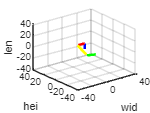


figure
quiver3(p0(1,1), p0(2,1), p0(3,1), Link1(1,1), Link1(2,1), Link1(3,1), 'Color', 'blue','LineWidth', 2)
hold on
quiver3(p1(1,1), p1(2,1), p1(3,1), Link2(1,1), Link2(2,1), Link2(3,1), 'Color', 'red','LineWidth', 2)
hold on
quiver3(p2(1,1), p2(2,1), p2(3,1), Link3(1,1), Link3(2,1), Link3(3,1), 'Color', 'yellow','LineWidth', 2)
hold on
quiver3(p3(1,1), p3(2,1), p3(3,1), Link4(1,1), Link4(2,1), Link4(3,1), 'Color', 'green','LineWidth', 2)
xlabel('width')
ylabel('height')
zlabel('length')
axis([-40 40 -40 40 -40 40])

% Right Back Leg Kinematics
syms L1 L2xy L2z L3 theta1 theta2 theta3;

% Right Front Shoulder to Preprocessing UpperArm
angle01=theta1;

$$angle01 = \theta_{1}$$

p01=p(0,0,-L1);

$$p01 = \left(\begin{array}{c} 0\\ 0\\ -L_{1} \end{array}\right)$$

Rot01=Rotz(angle01);

$$Rot01 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

T01=HomogeneousTransform(Rot01, p01, 1)

$$T01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & -L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Right Front Preprocessing UpperArm to UpperArm
angle12z=-pi/2;

angle12z = -1.5708

angle12x=pi/2;

angle12x = 1.5708

p12=p(0, 0, 0);

$$p12 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Rot12=Rotz(angle12z)*Rotx(angle12x);

$$Rot12 = \left(\begin{array}{ccc} 0 & 0 & -1\\ -1 & 0 & 0\\ 0 & 1 & 0 \end{array}\right)$$

T12=HomogeneousTransform(Rot12, p12, 1)

$$T12 = \left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ -1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Right Front UpperArm to LowArm
angle23=theta2;

$$angle23 = \theta_{2}$$

p23=p(L2xy*cos(theta2),L2xy*sin(theta2),L2z);

$$p23 = \left(\begin{array}{c} \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\\ \mathrm{L2xy}\,\sin\left(\theta_{2}\right)\\ \mathrm{L2z} \end{array}\right)$$

Rot23=Rotz(angle23);

$$Rot23 = \left(\begin{array}{ccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

T23=HomogeneousTransform(Rot23, p23, 1)

$$T23 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & \mathrm{L2xy}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & \mathrm{L2z}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Right Front LowArm to Foot
angle34=theta3;

$$angle34 = \theta_{3}$$

p34=p(L3*cos(theta3),L3*sin(theta3),0);

$$p34 = \left(\begin{array}{c} L_{3}\,\cos\left(\theta_{3}\right)\\ L_{3}\,\sin\left(\theta_{3}\right)\\ 0 \end{array}\right)$$

Rot34=Rotz(angle34);

$$Rot34 = \left(\begin{array}{ccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

T34=HomogeneousTransform(Rot34, p34, 1)

$$T34 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & L_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & L_{3}\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Right Front Shoulder to UpperArm
T02=T01*T12

$$T02 = \left(\begin{array}{cccc} \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ -\cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & -L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T02=simplify(T02)

$$T02 = \left(\begin{array}{cccc} \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ -\cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & -L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Right Front Shoulder to LowArm
T03=T02*T23

$$T03 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right) & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\mathrm{L2z}\,\cos\left(\theta_{1}\right)\\ -\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & -\mathrm{L2z}\,\sin\left(\theta_{1}\right)-\mathrm{L2xy}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & \mathrm{L2xy}\,\sin\left(\theta_{2}\right)-L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03=simplify(T03)

$$T03 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right) & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\mathrm{L2z}\,\cos\left(\theta_{1}\right)\\ -\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & -\mathrm{L2z}\,\sin\left(\theta_{1}\right)-\mathrm{L2xy}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & \mathrm{L2xy}\,\sin\left(\theta_{2}\right)-L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Right Front Shoulder to Foot
T04=T03*T34

$$T04 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & -\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right) & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\mathrm{L2z}\,\cos\left(\theta_{1}\right)+L_{3}\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-L_{3}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & L_{3}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\mathrm{L2xy}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-L_{3}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\mathrm{L2z}\,\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & 0 & \mathrm{L2xy}\,\sin\left(\theta_{2}\right)-L_{1}+L_{3}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+L_{3}\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T04=simplify(T04)

$$T04 = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\mathrm{L2z}\,\cos\left(\theta_{1}\right)+L_{3}\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-L_{3}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ -\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & L_{3}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\mathrm{L2xy}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-L_{3}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\mathrm{L2z}\,\sin\left(\theta_{1}\right)\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)-L_{1}+\mathrm{L2xy}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Right Front Leg Kinematics test by plot graph

% Right Front Shoulder to Preprocessing UpperArm
angle01=0;

angle01 = 0

p01=p(0,0,-10);

$$p01 = \left(\begin{array}{c} 0\\ 0\\ -10 \end{array}\right)$$

Rot01=Rotz(angle01);

$$Rot01 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

T01=HomogeneousTransform(Rot01, p01, 1)

$$T01 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -10\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Right Front Preprocessing UpperArm to UpperArm
angle12z=-pi/2;

angle12z = -1.5708

angle12x=pi/2;

angle12x = 1.5708

p12=p(0, 0, 0);

$$p12 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Rot12=Rotz(angle12z)*Rotx(angle12x);

$$Rot12 = \left(\begin{array}{ccc} 0 & 0 & -1\\ -1 & 0 & 0\\ 0 & 1 & 0 \end{array}\right)$$

T12=HomogeneousTransform(Rot12, p12, 1)

$$T12 = \left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ -1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Right Front UpperArm to LowArm
angle23=-pi/6;

angle23 = -0.5236

p23=p(20*cos(-pi/6),20*sin(-pi/6),10);

$$p23 = \left(\begin{array}{c} 10\,\sqrt{3}\\ -10\\ 10 \end{array}\right)$$

Rot23=Rotz(angle23);

$$Rot23 = \left(\begin{array}{ccc} \frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\ -\frac{1}{2} & \frac{\sqrt{3}}{2} & 0\\ 0 & 0 & 1 \end{array}\right)$$

T23=HomogeneousTransform(Rot23, p23, 1)

$$T23 = \left(\begin{array}{cccc} \frac{\sqrt{3}}{2} & \frac{1}{2} & 0 & 10\,\sqrt{3}\\ -\frac{1}{2} & \frac{\sqrt{3}}{2} & 0 & -10\\ 0 & 0 & 1 & 10\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Right Front LowArm to Foot
angle34=pi/3;

angle34 = 1.0472

p34=p(20*cos(pi/3),20*sin(pi/3),0);

$$p34 = \left(\begin{array}{c} 10\\ 10\,\sqrt{3}\\ 0 \end{array}\right)$$

Rot34=Rotz(angle34);

$$Rot34 = \left(\begin{array}{ccc} \frac{1}{2} & -\frac{\sqrt{3}}{2} & 0\\ \frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\ 0 & 0 & 1 \end{array}\right)$$

T34=HomogeneousTransform(Rot34, p34, 1)

$$T34 = \left(\begin{array}{cccc} \frac{1}{2} & -\frac{\sqrt{3}}{2} & 0 & 10\\ \frac{\sqrt{3}}{2} & \frac{1}{2} & 0 & 10\,\sqrt{3}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Right Front Shoulder to UpperArm
T02=T01*T12

$$T02 = \left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ -1 & 0 & 0 & 0\\ 0 & 1 & 0 & -10\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Right Front Shoulder to LowArm
T03=T02*T23

$$T03 = \left(\begin{array}{cccc} 0 & 0 & -1 & -10\\ -\frac{\sqrt{3}}{2} & -\frac{1}{2} & 0 & -10\,\sqrt{3}\\ -\frac{1}{2} & \frac{\sqrt{3}}{2} & 0 & -20\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Right Front Shoulder to Foot
T04=T03*T34

$$T04 = \left(\begin{array}{cccc} 0 & 0 & -1 & -10\\ -\frac{\sqrt{3}}{2} & \frac{1}{2} & 0 & -20\,\sqrt{3}\\ \frac{1}{2} & \frac{\sqrt{3}}{2} & 0 & -10\\ 0 & 0 & 0 & 1 \end{array}\right)$$


p0=PosExtract;

p0 =      0
     0
     0
     1


p1=T01*PosExtract;

$$p1 = \left(\begin{array}{c} 0\\ 0\\ -10\\ 1 \end{array}\right)$$

p2=T02*[0 0 10 1].';

$$p2 = \left(\begin{array}{c} -10\\ 0\\ -10\\ 1 \end{array}\right)$$

p3=T03*PosExtract;

$$p3 = \left(\begin{array}{c} -10\\ -10\,\sqrt{3}\\ -20\\ 1 \end{array}\right)$$

p4=T04*PosExtract;

$$p4 = \left(\begin{array}{c} -10\\ -20\,\sqrt{3}\\ -10\\ 1 \end{array}\right)$$


Link1=p1-p0;

$$Link1 = \left(\begin{array}{c} 0\\ 0\\ -10\\ 0 \end{array}\right)$$

Link2=p2-p1;

$$Link2 = \left(\begin{array}{c} -10\\ 0\\ 0\\ 0 \end{array}\right)$$

Link3=p3-p2;

$$Link3 = \left(\begin{array}{c} 0\\ -10\,\sqrt{3}\\ -10\\ 0 \end{array}\right)$$

Link4=p4-p3;

$$Link4 = \left(\begin{array}{c} 0\\ -10\,\sqrt{3}\\ 10\\ 0 \end{array}\right)$$

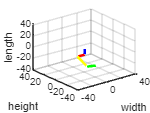


figure
quiver3(p0(1,1), p0(2,1), p0(3,1), Link1(1,1), Link1(2,1), Link1(3,1), 'Color', 'blue','LineWidth', 2)
hold on
quiver3(p1(1,1), p1(2,1), p1(3,1), Link2(1,1), Link2(2,1), Link2(3,1), 'Color', 'red','LineWidth', 2)
hold on
quiver3(p2(1,1), p2(2,1), p2(3,1), Link3(1,1), Link3(2,1), Link3(3,1), 'Color', 'yellow','LineWidth', 2)
hold on
quiver3(p3(1,1), p3(2,1), p3(3,1), Link4(1,1), Link4(2,1), Link4(3,1), 'Color', 'green','LineWidth', 2)
xlabel('width')
ylabel('height')
zlabel('length')
axis([-40 40 -40 40 -40 40])

% Left Front Leg Kinematics
syms L1 L2xy L2z L3 theta1 theta2 theta3

% Right Front Shoulder to Preprocessing UpperArm
angle01=theta1
p01=p(0,0,L1)
Rot01=Rotz(angle01)
T01=HomogeneousTransform(Rot01, p01, 1)

% Right Front Preprocessing UpperArm to UpperArm
angle12z=-pi/2
angle12x=pi/2
p12=p(0, 0, 0)
Rot12=Rotz(angle12z)*Rotx(angle12x)
T12=HomogeneousTransform(Rot12, p12, 1)

% Right Front UpperArm to LowArm
angle23=theta2
p23=p(L2xy*cos(theta2),L2xy*sin(theta2),L2z)
Rot23=Rotz(angle23)
T23=HomogeneousTransform(Rot23, p23, 1)

% Right Front LowArm to Foot
angle34=theta3
p34=p(L3*cos(theta3),L3*sin(theta3),0)
Rot34=Rotz(angle34)
T34=HomogeneousTransform(Rot34, p34, 1)

% Right Front Shoulder to UpperArm
T02=T01*T12
T02=simplify(T02)
% Right Front Shoulder to LowArm
T03=T02*T23
T03=simplify(T03)
% Right Front Shoulder to Foot
T04=T03*T34
T04=simplify(T04)

$$T01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 =      0     0    -1     0
    -1     0     0     0
     0     1     0     0
     0     0     0     1


$$T23 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & \mathrm{L2xy}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & \mathrm{L2z}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T34 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & L_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & L_{3}\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T02 = \left(\begin{array}{cccc} \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ -\cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T03 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right) & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\mathrm{L2z}\,\cos\left(\theta_{1}\right)\\ -\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & -\mathrm{L2z}\,\sin\left(\theta_{1}\right)-\mathrm{L2xy}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & L_{1}+\mathrm{L2xy}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T04 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & -\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right) & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\mathrm{L2z}\,\cos\left(\theta_{1}\right)+L_{3}\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-L_{3}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & L_{3}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\mathrm{L2xy}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-L_{3}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\mathrm{L2z}\,\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & 0 & L_{1}+\mathrm{L2xy}\,\sin\left(\theta_{2}\right)+L_{3}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+L_{3}\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T02 = \left(\begin{array}{cccc} \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ -\cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T03 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right) & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\mathrm{L2z}\,\cos\left(\theta_{1}\right)\\ -\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & -\mathrm{L2z}\,\sin\left(\theta_{1}\right)-\mathrm{L2xy}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & L_{1}+\mathrm{L2xy}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T04 = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\mathrm{L2z}\,\cos\left(\theta_{1}\right)+L_{3}\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-L_{3}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ -\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & L_{3}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\mathrm{L2xy}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-L_{3}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\mathrm{L2z}\,\sin\left(\theta_{1}\right)\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & L_{1}+L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+\mathrm{L2xy}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Left Back Leg Kinematics
syms L1 L2xy L2z L3 theta1 theta2 theta3

% Right Front Shoulder to Preprocessing UpperArm
angle01=theta1
p01=p(0,0,L1)
Rot01=Rotz(angle01)
T01=HomogeneousTransform(Rot01, p01, 1)

% Right Front Preprocessing UpperArm to UpperArm
angle12z=-pi/2
angle12x=pi/2
p12=p(0, 0, 0)
Rot12=Rotz(angle12z)*Rotx(angle12x)
T12=HomogeneousTransform(Rot12, p12, 1)

% Right Front UpperArm to LowArm
angle23=theta2
p23=p(L2xy*cos(theta2),L2xy*sin(theta2),L2z)
Rot23=Rotz(angle23)
T23=HomogeneousTransform(Rot23, p23, 1)

% Right Front LowArm to Foot
angle34=theta3
p34=p(L3*cos(theta3),L3*sin(theta3),0)
Rot34=Rotz(angle34)
T34=HomogeneousTransform(Rot34, p34, 1)

% Right Front Shoulder to UpperArm
T02=T01*T12
T02=simplify(T02)
% Right Front Shoulder to LowArm
T03=T02*T23
T03=simplify(T03)
% Right Front Shoulder to Foot
T04=T03*T34
T04=simplify(T04)

$$T01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 =      0     0    -1     0
    -1     0     0     0
     0     1     0     0
     0     0     0     1


$$T23 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & \mathrm{L2xy}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & \mathrm{L2z}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T34 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & L_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & L_{3}\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T02 = \left(\begin{array}{cccc} \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ -\cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T03 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right) & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\mathrm{L2z}\,\cos\left(\theta_{1}\right)\\ -\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & -\mathrm{L2z}\,\sin\left(\theta_{1}\right)-\mathrm{L2xy}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & L_{1}+\mathrm{L2xy}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T04 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & -\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right) & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\mathrm{L2z}\,\cos\left(\theta_{1}\right)+L_{3}\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-L_{3}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & L_{3}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\mathrm{L2xy}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-L_{3}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\mathrm{L2z}\,\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & 0 & L_{1}+\mathrm{L2xy}\,\sin\left(\theta_{2}\right)+L_{3}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+L_{3}\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T02 = \left(\begin{array}{cccc} \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ -\cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T03 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right) & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\mathrm{L2z}\,\cos\left(\theta_{1}\right)\\ -\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & -\mathrm{L2z}\,\sin\left(\theta_{1}\right)-\mathrm{L2xy}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & L_{1}+\mathrm{L2xy}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T04 = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \mathrm{L2xy}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-\mathrm{L2z}\,\cos\left(\theta_{1}\right)+L_{3}\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-L_{3}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ -\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & L_{3}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\mathrm{L2xy}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-L_{3}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\mathrm{L2z}\,\sin\left(\theta_{1}\right)\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & L_{1}+L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+\mathrm{L2xy}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$